## Setting up model

clear

init_basketball_shooting;
mdl = 'model_basketball_shooting';
open_system(mdl)

% Add none/some back spin
w0    = 360 * 2;   % deg/s


## Create the variables, simulate model & gather results

Create a Simulink.SimulationInput object and set the variables used by the model

% combinations release angle and initial velocity
load('simDataPhiV0.mat','phi_v0_fit');
phi_vec = 45:2:65;
v0_vec  = phi_v0_fit(phi_vec)';

% initialize some arrays
v0_list    = cell(size(phi_vec));
phi_list   = cell(size(phi_vec));
makes_list = cell(size(phi_vec));

N = 1000; % number of shots for each v0-phi combination

% quasi-random space-filling number sequence (Sobol)
p = sobolset(2,'Skip',1e3,'Leap',1e2);
p = scramble(p,'MatousekAffineOwen');
var_seq = net(p,N);   % get the uniformly distributed sequence
var_seq = icdf('Normal',var_seq,0,1);   % inverse tranform to normal distribution
% histogram(var_seq(:,1)); 
% histogram(var_seq(:,2));

for i = 1:length(phi_vec)

    % add random noise around a mean
    v0_list{i}  =  v0_vec(i) + var_seq(:,1)*0.1;
    phi_list{i} = phi_vec(i) + var_seq(:,2)*1.0;
    % histogram( v0_list{i}); drawnow
    % histogram(phi_list{i}); drawnow

    % create Simulink Inputs & variables
    for ii = 1:N
        in(ii) = Simulink.SimulationInput(mdl);
        in(ii) = in(ii).setVariable('phi',phi_list{i}(ii)); 
        in(ii) = in(ii).setVariable('v0' , v0_list{i}(ii)); 
    end

    % Simulate the model
    % out = sim(in);  % simulation in series
    out = parsim(in,'TransferBaseWorkspaceVariables','on');  % simulation in parallel

    % gather results on if a shot is made
    makes_list{i} = zeros(1,N);
    for ii = 1:N
        makes_list{i}(ii) = max(out(ii).yout.get('made').Values.Data);
    end

end

[30-Jul-2023 11:30:56] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
[30-Jul-2023 11:31:14] Starting Simulink on parallel workers...
[30-Jul-2023 11:31:20] Configuring simulation cache folder on parallel workers...
[30-Jul-2023 11:31:20] Transferring base workspace variables used in the model to parallel workers...
[30-Jul-2023 11:31:21] Loading model on parallel workers...
[30-Jul-2023 11:31:29] Running simulations...
[30-Jul-2023 11:31:57] Completed 1 of 1000 simulation runs
[30-Jul-2023 11:31:57] Completed 2 of 1000 simulation runs
[30-Jul-2023 11:31:57] Completed 3 of 1000 simulation runs
[30-Jul-2023 11:31:57] Completed 4 of 1000 simulation runs
[30-Jul-2023 11:31:58] Completed 5 of 1000 simulation runs
[30-Jul-2023 11:31:58] Completed 6 of 1000 simulation runs
[30-Jul-2023 11:32:00] Completed 7 of 1000 simulation runs
[30-Jul-2023 11:32:00] Completed 8 of 1000 simulation 

## Plot shots

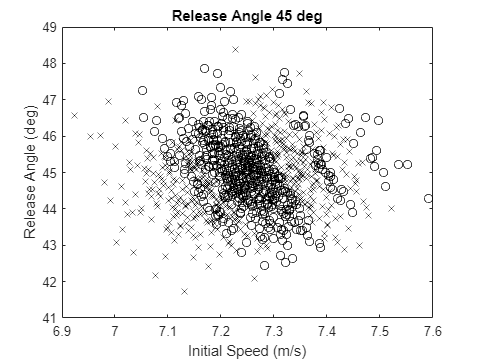

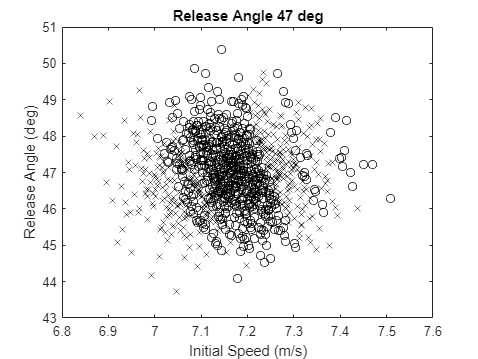

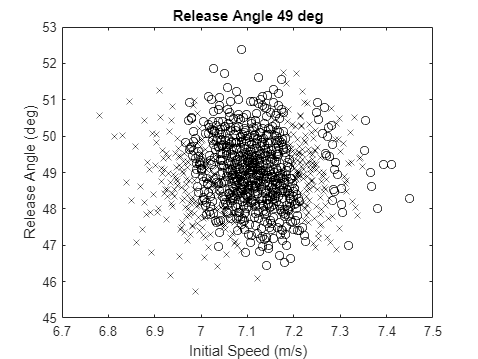

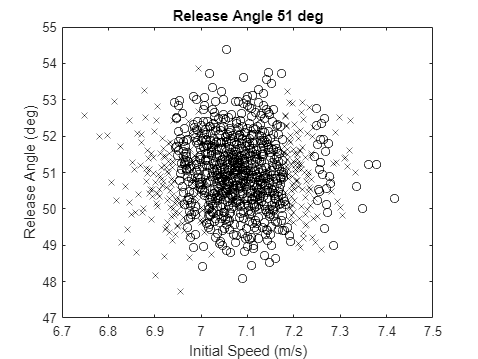

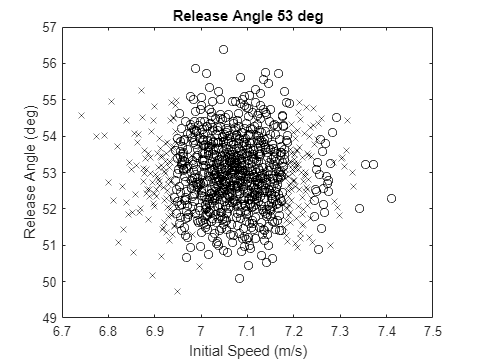

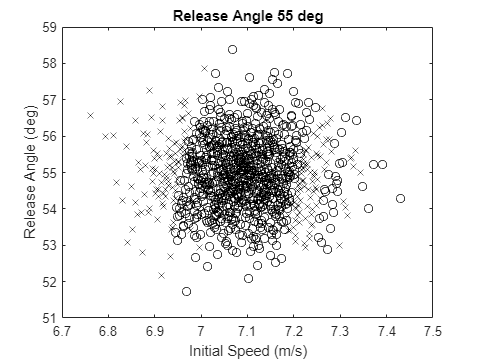

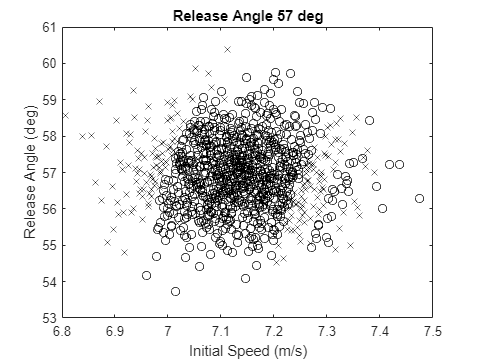

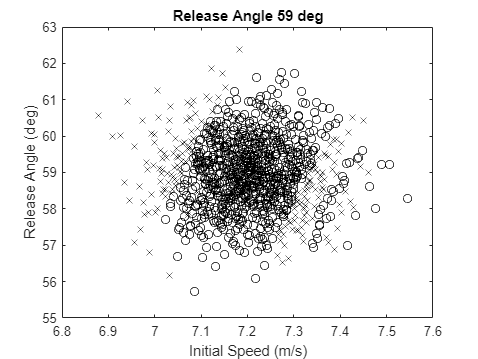

for i = 1:length(v0_vec)
    figure(100+i); clf;
    title("Release Angle "+num2str(phi_vec(i))+" deg")
    hold on
    index = makes_list{i}==1;  % makes
    scatter(v0_list{i}(index), phi_list{i}(index),40,[0 0 0],'o')
    index = makes_list{i}==0;  % misses
    scatter(v0_list{i}(index), phi_list{i}(index),40,[0 0 0],'x')
    hold off
    xlabel('Initial Speed (m/s)')
    ylabel('Release Angle (deg)')
    box on
end

## Summary

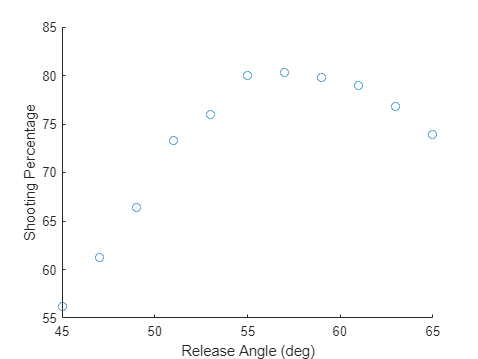

make_pct = zeros(size(v0_vec));
for i = 1:length(v0_vec)
    make_pct(i) = sum(makes_list{i})/length(makes_list{i}) * 100;
end
figure(201); clf;
scatter(phi_vec,make_pct);
xlabel('Release Angle (deg)')
ylabel('Shooting Percentage')

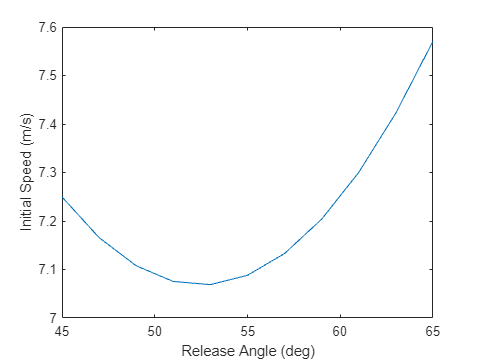


figure(202); clf;
plot(phi_vec,v0_vec);
xlabel('Release Angle (deg)')
ylabel('Initial Speed (m/s)')


% save("simDataPhi0.mat",'make_pct','v0_vec','phi_vec','makes_list','v0_list','phi_list')
save("simDataPhi2.mat",'make_pct','v0_vec','phi_vec','makes_list','v0_list','phi_list')
